# Diseño de controlador en cascada

close all
clear all
% Función de transferencia de velocidad del motor
G = tf(273,[1  4.112]) % Planta del laboratorio pasado


G =
 
     273
  ---------
  s + 4.112
 
Continuous-time transfer function.
Model Properties


%Parámetros de diseño
Tes = 1 % (3 veces más rápido)

Tes = 1

Mp = 0.1; % 10% 

Diseño del lazo interno

% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -4.0000 + 5.4575i

s2 = -sigma-wd*1j

s2 = -4.0000 - 5.4575i


so = -2*sigma

so = -8

% Controlador
Ti = -1/so

Ti = 0.1250


Gc_p = tf([1 1/Ti], [1 0])


Gc_p =
 
  s + 8
  -----
    s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G


Gol =
 
  273 s + 2184
  -------------
  s^2 + 4.112 s
 
Continuous-time transfer function.
Model Properties


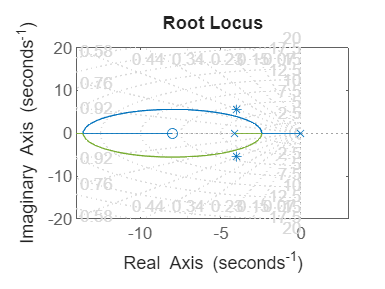

figure(1)
rlocus(Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
axis([-14 3 -20  20])
hold off

Kp= 0.016;
%En lazo cerrado
Glc = feedback(Kp*Gol,1)


Glc =
 
    4.368 s + 34.94
  --------------------
  s^2 + 8.48 s + 34.94
 
Continuous-time transfer function.
Model Properties



figure(2)
step(Glc);
grid on

% Tiempo de subida
Tr = 0.382 - 0.0119

Tr = 0.3701

Tr_ref = Tr/10

Tr_ref = 0.0370

T = 0.030 % 30 ms

T = 0.0300

Diseño de lazo externo

G2 = Glc*tf(1, [1 0]) % Lazo cerrado por integrador


G2 =
 
      4.368 s + 34.94
  ------------------------
  s^3 + 8.48 s^2 + 34.94 s
 
Continuous-time transfer function.
Model Properties



%Parámetros de diseño (lazo externo)
Tese = 3 

Tese = 3

Mpe = 0.05; % 5% 

sigmae = 4/Tese;
wde = -pi*sigmae/log(Mpe);
se1 = -sigmae+wde*1j

se1 = -1.3333 + 1.3983i

se2 = -sigmae-wde*1j

se2 = -1.3333 - 1.3983i

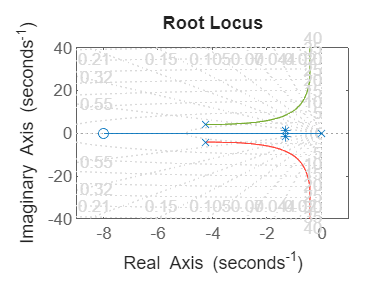



figure(3)
rlocus(G2)
grid on
hold on
plot([-sigmae  -sigmae],[wde  -wde],'*')
% axis([-14 3 -12  12])
hold off

Kpe = 1.22;
Glce = feedback(Kpe*G2, 1)


Glce =
 
          5.329 s + 42.63
  --------------------------------
  s^3 + 8.48 s^2 + 40.27 s + 42.63
 
Continuous-time transfer function.
Model Properties


figure(4)
step(Glce)
grid on

Te = 3*T

Te = 0.0900

Resultados en XSpace

% Datos XSpace
SP100 = [0.00  0.00  0.00
30.00  2.11  0.00
60.00  2.26  0.28
90.00  2.02  1.12
120.00  1.85  2.53
150.00  1.75  4.50
180.00  1.62  6.19
210.00  1.53  8.72
240.00  1.65  10.41
270.00  1.59  12.38
300.00  1.63  14.63
330.00  1.57  17.16
360.00  1.37  19.41
390.00  1.58  21.94
420.00  1.58  23.62
450.00  1.54  26.16
480.00  1.56  28.12
510.00  1.49  30.37
540.00  1.52  32.34
570.00  1.55  34.59
600.00  1.45  36.56
630.00  1.47  38.81
660.00  1.49  40.78
690.00  1.41  43.03
720.00  1.42  45.00
750.00  1.46  46.97
780.00  1.34  48.94
810.00  1.36  50.91
840.00  1.31  53.16
870.00  1.27  55.13
900.00  1.32  56.81
930.00  1.24  58.50
960.00  1.25  60.47
990.00  1.27  61.88
1020.00  1.20  63.56
1050.00  1.21  65.25
1080.00  1.23  66.66
1110.00  1.15  68.34
1140.00  1.15  69.75
1170.00  1.17  71.16
1200.00  1.10  72.56
1230.00  1.10  73.97
1260.00  1.11  75.37
1290.00  1.04  76.50
1320.00  1.05  77.91
1350.00  1.07  79.03
1380.00  1.00  80.16
1410.00  1.01  81.28
1440.00  0.95  82.41
1470.00  0.95  83.53
1500.00  0.96  84.37
1530.00  0.92  85.50
1560.00  0.91  86.34
1590.00  0.93  87.19
1620.00  0.89  88.03
1650.00  0.88  88.87
1680.00  0.89  89.72
1710.00  0.84  90.28
1740.00  0.84  91.12
1770.00  0.84  91.97
1800.00  0.79  92.53
1830.00  0.79  93.09
1860.00  0.76  93.66
1890.00  0.76  94.22
1920.00  0.77  94.78
1950.00  0.73  95.34
1980.00  0.73  95.91
2010.00  0.73  96.47
2040.00  0.70  96.75
2070.00  0.70  97.31
2100.00  0.70  97.59
2130.00  0.67  98.16
2160.00  0.66  98.44
2190.00  0.66  98.72
2220.00  0.65  99.00
2250.00  0.64  99.28
2280.00  0.62  99.84
2310.00  0.61  99.84
2340.00  0.61  100.12
2370.00  0.59  100.41
2400.00  0.58  100.69
2430.00  0.57  100.97
2460.00  0.56  101.25
2490.00  0.56  101.25
2520.00  0.55  101.53
2550.00  0.54  101.81
2580.00  0.54  101.81
2610.00  0.54  102.09
2640.00  0.52  102.09
2670.00  0.51  102.09
2700.00  0.50  102.37
2730.00  0.49  102.37
2760.00  0.48  102.66
2790.00  0.47  102.66
2820.00  0.46  102.66
2850.00  0.45  102.66
2880.00  0.44  102.66
2910.00  0.43  102.66
2940.00  0.42  102.66
2970.00  0.41  102.66
3000.00  0.40  102.66
3030.00  0.39  102.66
3060.00  0.38  102.66
3090.00  0.37  102.66
3120.00  0.36  102.66
3150.00  0.35  102.66
3180.00  0.35  102.66
3210.00  0.34  102.66
3240.00  0.33  102.66
3270.00  0.32  102.66
3300.00  0.31  102.66
3330.00  0.30  102.66
3360.00  0.29  102.66
3390.00  0.28  102.66
3420.00  0.27  102.66
3450.00  0.26  102.66
3480.00  0.25  102.66
3510.00  0.24  102.66
3540.00  0.23  102.66
3570.00  0.22  102.66
3600.00  0.21  102.66
3630.00  0.20  102.66
3660.00  0.19  102.66
3690.00  0.18  102.66
3720.00  0.17  102.66
3750.00  0.16  102.66
3780.00  0.15  102.66
3810.00  0.14  102.66
3840.00  0.13  102.66
3870.00  0.12  102.66
3900.00  0.11  102.66
3930.00  0.10  102.66
3960.00  0.09  102.66
3990.00  0.08  102.66
4020.00  0.07  102.66
4050.00  0.06  102.66
4080.00  0.05  102.66
4110.00  0.04  102.66];

SP120 = [0.00  0.00  0.00
30.00  2.53  0.00
60.00  2.72  0.28
90.00  2.51  1.41
120.00  2.21  3.09
150.00  2.07  5.34
180.00  1.86  7.87
210.00  1.85  10.69
240.00  1.87  13.22
270.00  1.74  15.75
300.00  1.79  18.56
330.00  1.85  21.37
360.00  1.72  24.19
390.00  1.76  27.00
420.00  1.79  29.81
450.00  1.65  32.91
480.00  1.70  35.72
510.00  1.51  38.81
540.00  1.62  41.34
570.00  1.67  44.16
600.00  1.54  46.69
630.00  1.56  49.22
660.00  1.60  52.03
690.00  1.47  54.56
720.00  1.48  56.53
750.00  1.51  59.06
780.00  1.42  61.59
810.00  1.45  63.84
840.00  1.49  66.09
870.00  1.37  68.34
900.00  1.39  70.59
930.00  1.27  72.84
960.00  1.29  74.81
990.00  1.33  76.78
1020.00  1.23  78.75
1050.00  1.25  80.72
1080.00  1.28  82.41
1110.00  1.19  84.37
1140.00  1.20  86.06
1170.00  1.23  87.75
1200.00  1.14  89.16
1230.00  1.14  90.84
1260.00  1.17  92.53
1290.00  1.08  93.94
1320.00  1.09  95.34
1350.00  1.02  96.75
1380.00  1.04  97.87
1410.00  1.05  99.28
1440.00  0.99  100.41
1470.00  1.00  101.53
1500.00  1.01  102.66
1530.00  0.96  103.78
1560.00  0.96  104.62
1590.00  0.96  105.75
1620.00  0.92  106.59
1650.00  0.92  107.44
1680.00  0.92  108.28
1710.00  0.88  109.12
1740.00  0.87  109.97
1770.00  0.83  110.81
1800.00  0.83  111.37
1830.00  0.84  112.22
1860.00  0.80  112.78
1890.00  0.80  113.34
1920.00  0.80  113.91
1950.00  0.77  114.47
1980.00  0.76  115.03
2010.00  0.76  115.59
2040.00  0.73  116.16
2070.00  0.72  116.72
2100.00  0.72  117.00
2130.00  0.69  117.56
2160.00  0.68  118.12
2190.00  0.68  118.41
2220.00  0.66  118.69
2250.00  0.66  119.25
2280.00  0.63  119.53
2310.00  0.63  119.81
2340.00  0.63  120.09
2370.00  0.62  120.37
2400.00  0.61  120.66
2430.00  0.60  120.94
2460.00  0.58  120.94
2490.00  0.58  121.22
2520.00  0.57  121.50
2550.00  0.56  121.78
2580.00  0.55  121.78
2610.00  0.54  122.06
2640.00  0.52  122.06
2670.00  0.52  122.34
2700.00  0.51  122.34
2730.00  0.49  122.34
2760.00  0.48  122.34
2790.00  0.47  122.34
2820.00  0.46  122.34
2850.00  0.45  122.34
2880.00  0.44  122.34
2910.00  0.43  122.34
2940.00  0.42  122.34
2970.00  0.41  122.34
3000.00  0.40  122.34
3030.00  0.39  122.34
3060.00  0.37  122.34
3090.00  0.36  122.34
3120.00  0.35  122.34
3150.00  0.34  122.34
3180.00  0.33  122.34
3210.00  0.32  122.34
3240.00  0.31  122.34
3270.00  0.30  122.34
3300.00  0.29  122.34
3330.00  0.28  122.34
3360.00  0.27  122.34
3390.00  0.25  122.34
3420.00  0.24  122.34
3450.00  0.23  122.34
3480.00  0.22  122.34
3510.00  0.21  122.34
3540.00  0.20  122.34
3570.00  0.19  122.34
3600.00  0.18  122.34
3630.00  0.17  122.34
3660.00  0.16  122.34
3690.00  0.15  122.34
3720.00  0.13  122.34
3750.00  0.12  122.34
3780.00  0.11  122.34
3810.00  0.10  122.34
3840.00  0.09  122.34
3870.00  0.08  122.34
3900.00  0.07  122.34
3930.00  0.06  122.34
3960.00  0.05  122.34
3990.00  0.04  122.34
4020.00  0.03  122.34];

SP80 = [0.00  0.00  0.00
30.00  1.69  0.00
60.00  1.81  0.28
90.00  1.92  0.56
120.00  1.80  1.41
150.00  1.62  2.25
180.00  1.47  3.94
210.00  1.44  5.62
240.00  1.45  7.31
270.00  1.42  8.72
300.00  1.46  10.41
330.00  1.51  12.09
360.00  1.36  13.78
390.00  1.45  15.47
420.00  1.49  17.16
450.00  1.41  18.84
480.00  1.44  20.81
510.00  1.36  22.50
540.00  1.39  24.19
570.00  1.41  25.87
600.00  1.33  27.56
630.00  1.21  29.53
660.00  1.36  31.22
690.00  1.32  32.91
720.00  1.34  34.31
750.00  1.35  36.00
780.00  1.27  37.69
810.00  1.28  39.09
840.00  1.30  40.78
870.00  1.22  42.19
900.00  1.24  43.59
930.00  1.16  45.28
960.00  1.18  46.69
990.00  1.20  48.09
1020.00  1.13  49.50
1050.00  1.09  51.19
1080.00  1.14  52.31
1110.00  1.09  53.44
1140.00  1.10  54.84
1170.00  1.12  55.97
1200.00  1.05  57.09
1230.00  1.06  58.22
1260.00  1.06  59.34
1290.00  1.01  60.47
1320.00  1.01  61.31
1350.00  1.02  62.44
1380.00  0.96  63.28
1410.00  0.96  64.41
1440.00  0.92  65.25
1470.00  0.92  66.09
1500.00  0.93  66.94
1530.00  0.88  67.78
1560.00  0.89  68.62
1590.00  0.89  69.19
1620.00  0.85  70.03
1650.00  0.86  70.59
1680.00  0.85  71.44
1710.00  0.82  72.00
1740.00  0.82  72.56
1770.00  0.82  73.12
1800.00  0.79  73.69
1830.00  0.78  74.25
1860.00  0.75  74.81
1890.00  0.75  75.37
1920.00  0.75  75.66
1950.00  0.73  76.22
1980.00  0.73  76.50
2010.00  0.72  77.06
2040.00  0.71  77.34
2070.00  0.71  77.62
2100.00  0.70  78.19
2130.00  0.67  78.47
2160.00  0.67  78.75
2190.00  0.67  79.03
2220.00  0.64  79.31
2250.00  0.63  79.59
2280.00  0.61  79.87
2310.00  0.61  80.16
2340.00  0.61  80.44
2370.00  0.60  80.72
2400.00  0.59  80.72
2430.00  0.58  81.00
2460.00  0.56  81.28
2490.00  0.56  81.28
2520.00  0.56  81.56
2550.00  0.55  81.56
2580.00  0.54  81.84
2610.00  0.54  81.84
2640.00  0.53  81.84
2670.00  0.52  81.84
2700.00  0.51  81.84
2730.00  0.50  81.84
2760.00  0.49  81.84
2790.00  0.48  81.84
2820.00  0.47  81.84
2850.00  0.46  81.84
2880.00  0.46  81.84
2910.00  0.45  81.84
2940.00  0.44  81.84
2970.00  0.43  81.84
3000.00  0.42  81.84
3030.00  0.41  81.84
3060.00  0.40  81.84
3090.00  0.39  81.84
3120.00  0.38  81.84
3150.00  0.37  81.84
3180.00  0.36  81.84
3210.00  0.36  81.84
3240.00  0.35  81.84
3270.00  0.34  81.84
3300.00  0.33  81.84
3330.00  0.32  81.84
3360.00  0.31  81.84
3390.00  0.30  81.84
3420.00  0.29  81.84
3450.00  0.28  81.84
3480.00  0.27  81.84
3510.00  0.26  81.84
3540.00  0.26  81.84
3570.00  0.25  81.84
3600.00  0.24  81.84
3630.00  0.23  81.84
3660.00  0.22  81.84
3690.00  0.21  81.84
3720.00  0.20  81.84
3750.00  0.19  81.84
3780.00  0.18  81.84
3810.00  0.17  81.84
3840.00  0.17  81.84
3870.00  0.16  81.84
3900.00  0.15  81.84
3930.00  0.14  81.84
3960.00  0.13  81.84
3990.00  0.12  81.84
4020.00  0.11  81.84
4050.00  0.10  81.84
4080.00  0.09  81.84
4110.00  0.08  81.84
4140.00  0.07  81.84
4170.00  0.07  81.84
4200.00  0.06  81.84
4230.00  0.05  81.84
4260.00  0.04  81.84
4290.00  0.03  81.84
4320.00  0.02  81.84
4350.00  0.01  81.84];

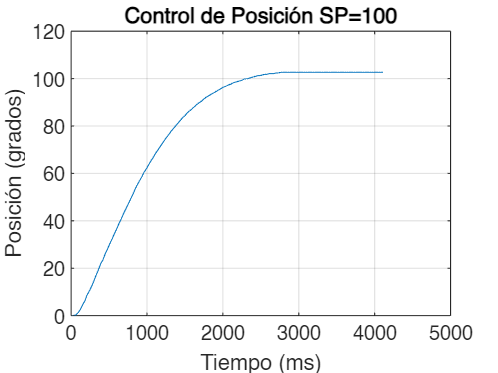

figure(5)
plot(SP100(:,1), SP100(:,3))
title('Control de Posición SP=100')
ylabel('Posición (grados)')
xlabel('Tiempo (ms)')
grid on

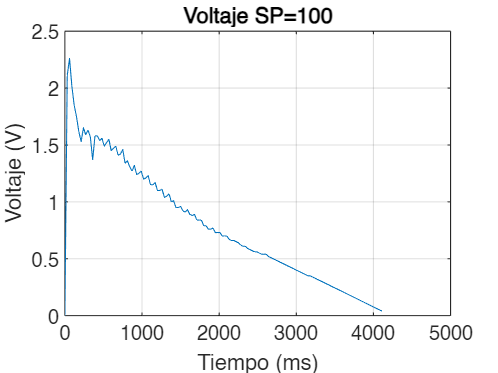


figure(6)
plot(SP100(:,1), SP100(:,2))
title('Voltaje SP=100')
ylabel('Voltaje (V)')
xlabel('Tiempo (ms)')
grid on

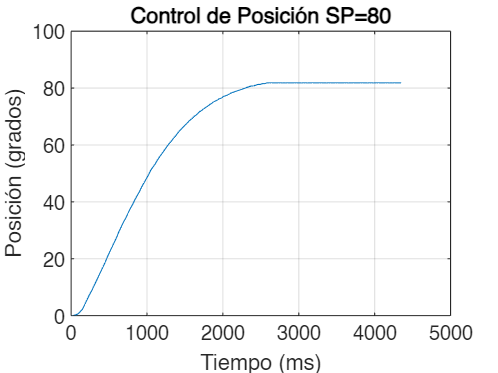


figure(7)
plot(SP80(:,1), SP80(:,3))
title('Control de Posición SP=80')
ylabel('Posición (grados)')
xlabel('Tiempo (ms)')
grid on

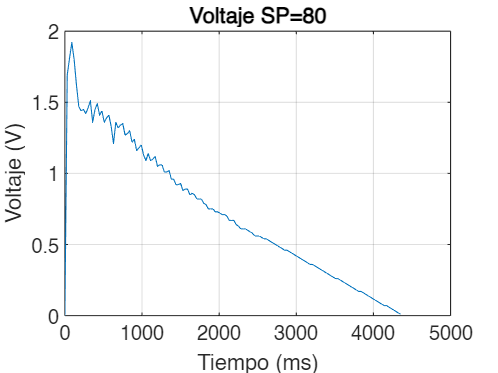


figure(8)
plot(SP80(:,1), SP80(:,2))
title('Voltaje SP=80')
ylabel('Voltaje (V)')
xlabel('Tiempo (ms)')
grid on

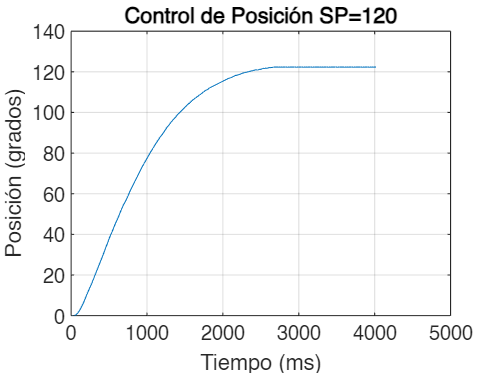


figure(9)
plot(SP120(:,1), SP120(:,3))
title('Control de Posición SP=120')
ylabel('Posición (grados)')
xlabel('Tiempo (ms)')
grid on

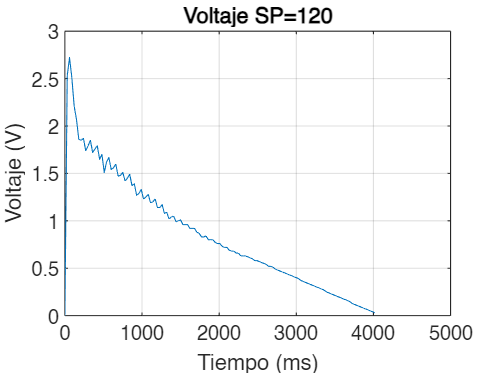


figure(10)
plot(SP120(:,1), SP120(:,2))
title('Voltaje SP=120')
ylabel('Voltaje (V)')
xlabel('Tiempo (ms)')
grid on